# Data Input and Output

The following will use the files: (obviously** you should change the file directory and name if you are not running it on Tom K's machine**)

datfile = 'C:\Users\Tom K\Google Drive\Programs\courses\CompProbSol\data\statepop'

datfile = 'C:\Users\Tom K\Google Drive\Programs\courses\CompProbSol\data\statepop'

txtfile = 'C:\Users\Tom K\Google Drive\Programs\courses\CompProbSol\data\GlobalTempbyYear.txt'

txtfile = 'C:\Users\Tom K\Google Drive\Programs\courses\CompProbSol\data\GlobalTempbyYear.txt'

csvfile = 'C:\Users\Tom K\Google Drive\Programs\courses\CompProbSol\data\sunspotsbyyear.csv'

csvfile = 'C:\Users\Tom K\Google Drive\Programs\courses\CompProbSol\data\sunspotsbyyear.csv'

xlsfile = 'C:\Users\Tom K\Google Drive\Programs\courses\CompProbSol\data\GlobalCarbonBudget2018.xlsx'

xlsfile = 'C:\Users\Tom K\Google Drive\Programs\courses\CompProbSol\data\GlobalCarbonBudget2018.xlsx'

## Inputting Data

Inputting data into a program can be the most time intensive activity.

MATLAB allows you to input (load) data in several ways

**By hand** – the old fashion way

-  very time consuming

-  prone to error

**GUI** – 

- straightforward and easy, 

- hard to systematize 

- accessible in the variable area of the HOME tab

**Command line** -  

- best way for a program you plan to run multiple times

- `load, csvread, xlsread, readtable, textscan`

## `By Hand`

Please do not input large amounts of data by hand

- You'll introduce errors

- And drive yourself crazy

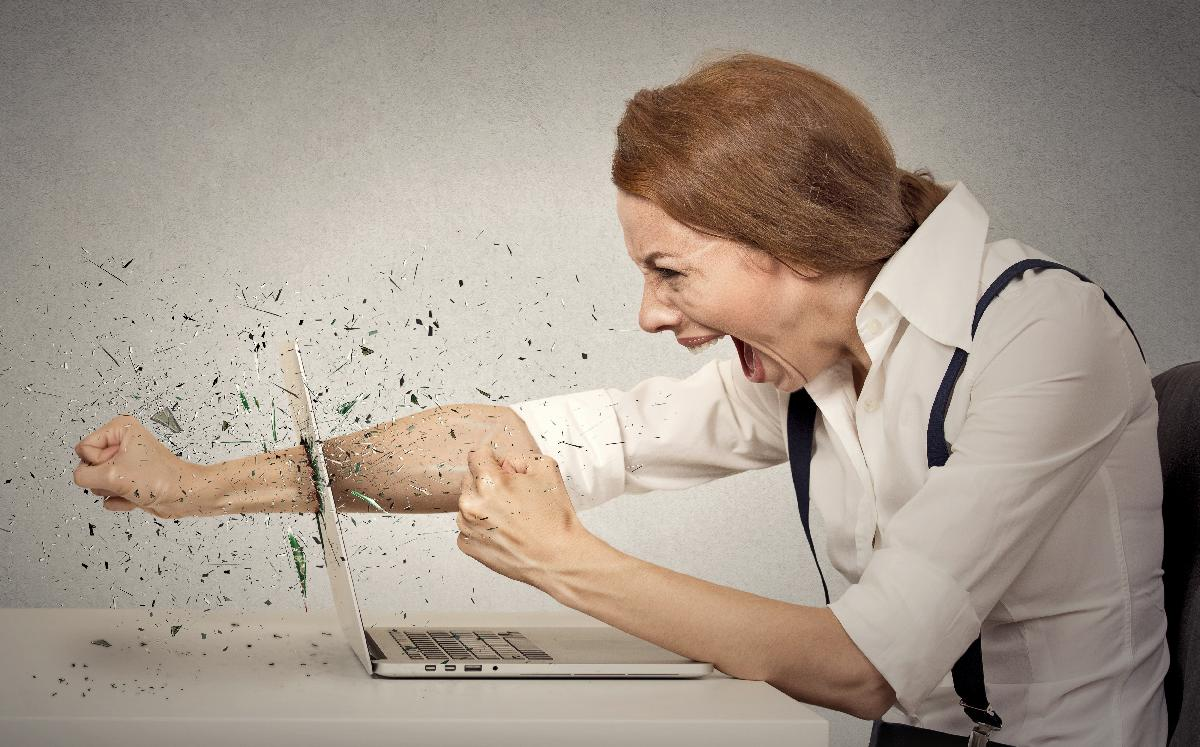

When to put input data by hand?

- If it takes less than a minute

- if your data isn't in electronic form 

## GUI

The variable area of the HOME tab allows you to

- create, edit, and save variables in your workspace

- import all or a portion of .txt, .xls, .csv, .mat, .dat files

- see and name columns of data in file

`uiimport` - command brings up the import GUI

## Command Line Commands

`load` – loads numeric variables into MATLAB

`csvread` – loads numeric values from a .csv file 

`xlsread` – loads texts and numeric values from .xls, .xlsx, .xlsm, .xltx, and .xltm files 

`readtable` – creates a table of variables from the columns of a file

`textscan`  - reads formatted text into a cell array 

`importdata` – loads data (including images) from a file, can specify delimiter and column headings 

## `LOAD`

- works for many file types, (but usually only ascii files,** really I would only use this for .mat files**)

- otherwise data should be numeric – is imported as doubles

load(datfile)

## `IMPORTDATA`

- most general of the functions (can import images)

- can specify delimiter (`delimiterIn`) and header lines (`headerlinesIn`)

- can output MATLAB's best guess at column delimiter (`delimiterOut`) and number of header lines (`headerlinesOut`)

Example setting `' '` (space) as a delimiter (what separates values). importdata reads .csv files well enough.

A = importdata(txtfile,'') 

A = 169×1 cell array
    {'1850   -0.373   -0.425   -0.339   -0.502   -0.243   -0.536   -0.210   -0.515   -0.238   -0.591   -0.162'}
    {'1851   -0.218   -0.274   -0.184   -0.350   -0.086   -0.368   -0.068   -0.365   -0.081   -0.429   -0.016'}
    {'1852   -0.228   -0.280   -0.196   -0.353   -0.103   -0.378   -0.078   -0.367   -0.098   -0.434   -0.030'}
    {'1853   -0.269   -0.321   -0.239   -0.378   -0.160   -0.428   -0.110   -0.393   -0.155   -0.472   -0.075'}
    {'1854   -0.248   -0.301   -0.218   -0.349   -0.147   -0.391   -0.105   -0.365   -0.143   -0.435   -0.072'}
    {'1855   -0.272   -0.324   -0.241   -0.369   -0.176   -0.415   -0.130   -0.385   -0.171   -0.455   -0.099'}
    {'1856   -0.358   -0.413   -0.327   -0.456   -0.260   -0.501   -0.215   -0.471   -0.253   -0.541   -0.182'}
    {'1857   -0.461   -0.512   -0.431   -0.558   -0.363   -0.594   -0.328   -0.573   -0.358   -0.636   -0.294'}
    {'1858   -0.467   -0.521   -0.435   -0.570   -0.364   -0.600   -0.334   -0.583 

B = importdata(csvfile)

B = 	1.0e+03 *

   1.700500000000000   0.008300000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.701500000000000   0.018300000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.702500000000000   0.026700000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.703500000000000   0.038300000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.704500000000000   0.060000000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.705500000000000   0.096700000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.706500000000000   0.048300000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.707500000000000   0.033300000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.708500000000000   0.016700000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.709500000000000   0.013300000000000  -0.001000000000000  -0.0010000000

## `CSVREAD`

- works for .csv files containing strictly numeric values

- stores all values in large matrix M

- can start at arbitrary column and row, *R1 C1 …*

Example using .csv file 

M = csvread(csvfile)

M = 	1.0e+03 *

   1.700500000000000   0.008300000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.701500000000000   0.018300000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.702500000000000   0.026700000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.703500000000000   0.038300000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.704500000000000   0.060000000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.705500000000000   0.096700000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.706500000000000   0.048300000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.707500000000000   0.033300000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.708500000000000   0.016700000000000  -0.001000000000000  -0.001000000000000   0.001000000000000
   1.709500000000000   0.013300000000000  -0.001000000000000  -0.0010000000

## `XLSREAD`

- reads all numeric data into the matrix X 

- can specify excel sheet and range

- can include output variables to capture text

Example using a quite complicated .xlsx file

X = xlsread(xlsfile, 'Global Carbon Budget','A23:F78')

X = 	1.0e+03 *

    1.9610    0.0026    0.0016    0.0017    0.0007    0.0006
    1.9620    0.0027    0.0016    0.0012    0.0008    0.0013
    1.9630    0.0028    0.0015    0.0012    0.0009    0.0009
    1.9640    0.0030    0.0015    0.0010    0.0011    0.0014
    1.9650    0.0031    0.0014    0.0023    0.0013    0.0004
    1.9660    0.0033    0.0014    0.0023    0.0013    0.0013
    1.9670    0.0034    0.0014    0.0013    0.0011    0.0016
    1.9680    0.0036    0.0014    0.0021    0.0011    0.0025
    1.9690    0.0038    0.0014    0.0028    0.0011    0.0005
    1.9700    0.0041    0.0013    0.0024    0.0011    0.0004


[num,txt,raw] = xlsread(xlsfile, 'Global Carbon Budget','A20:F79')

num = 	1.0e+03 *

    1.9590    0.0025    0.0018    0.0020    0.0009    0.0005
    1.9600    0.0026    0.0017    0.0015    0.0008    0.0014
    1.9610    0.0026    0.0016    0.0017    0.0007    0.0006
    1.9620    0.0027    0.0016    0.0012    0.0008    0.0013
    1.9630    0.0028    0.0015    0.0012    0.0009    0.0009
    1.9640    0.0030    0.0015    0.0010    0.0011    0.0014
    1.9650    0.0031    0.0014    0.0023    0.0013    0.0004
    1.9660    0.0033    0.0014    0.0023    0.0013    0.0013
    1.9670    0.0034    0.0014    0.0013    0.0011    0.0016
    1.9680    0.0036    0.0014    0.0021    0.0011    0.0025


txt = 1×6 cell array
    {'Year'}    {'fossil fuel and industry'}    {'land-use change emissions'}    {'atmospheric growth'}    {'ocean sink'}    {'land sink'}


raw = 60×6 cell array
    {'Year'}    {'fossil fuel and industry'}    {'land-use change emissions'}    {'atmospheric growth'}    {'ocean sink'}    {'land sink'}
    {[1959]}    {[                  2.4534]}    {[                   1.8106]}    {[            2.0352]}    {[    0.8524]}    {[   0.5161]}
    {[1960]}    {[                  2.5684]}    {[                   1.6726]}    {[            1.5052]}    {[    0.8190]}    {[   1.3940]}
    {[1961]}    {[                  2.5797]}    {[                   1.6076]}    {[            1.6536]}    {[    0.7148]}    {[   0.6051]}
    {[1962]}    {[                  2.6851]}    {[                   1.5668]}    {[            1.1872]}    {[    0.7567]}    {[   1.3483]}
    {[1963]}    {[                  2.8327]}    {[                   1.5138]}    {[            1.2084]}    {[    0.9050]}    {[   0.8778]}
    {[1964]}    {[                  2.9938]}    {[                   1.4639]}    {[            1.0388]}    {[    1.1418]}    {[   1.4006]}
    {

The advanced option for reading data from an xls file may be to capture the headers as well. You can do this with the following

T = cell2table(raw(2:end,:))

T = 59×6 table
    Var1     Var2      Var3      Var4      Var5       Var6  
    ____    ______    ______    ______    _______    _______

    1959    2.4534    1.8106    2.0352    0.85238    0.51607
    1960    2.5684    1.6726    1.5052    0.81902      1.394
    1961    2.5797    1.6076    1.6536    0.71484     0.6051
    1962    2.6851    1.5668    1.1872    0.75671     1.3483
    1963    2.8327    1.5138    1.2084      0.905    0.87779
    1964    2.9938    1.4639    1.0388     1.1418     1.4006
    1965    3.1294    1.4177     2.332     1.2928    0.42323
    1966    3.2875     1.376     2.332     1.2767     1.2784
    1967    3.3927    1.3548    1.2932     1.0702     1.6284
    1968    3.5654    1.3537    2.0988     1.1007     2.5306
    1969     3.779    1.3627    2.7984     1.138

match = [" " , "-"];
newraw = erase(raw(1,:),match);
% spaces are no good in table header names
T.Properties.VariableNames = newraw

T = 59×6 table
    Year    fossilfuelandindustry    landusechangeemissions    atmosphericgrowth    oceansink    landsink
    ____    _____________________    ______________________    _________________    _________    ________

    1959           2.4534                    1.8106                 2.0352           0.85238     0.51607 
    1960           2.5684                    1.6726                 1.5052           0.81902       1.394 
    1961           2.5797                    1.6076                 1.6536           0.71484      0.6051 
    1962           2.6851                    1.5668                 1.1872           0.75671      1.3483 
    1963           2.8327                    1.5138                 1.2084             0.905     0.87779 
    1964           2.9938             

## `READTABLE`

- creates a table from column data in a file

- `T` contains one variable per column in data file

Ttxt = readtable(txtfile)

Ttxt = 169×1 table
                                                       Var1                                                    
    ___________________________________________________________________________________________________________

    {'1850   -0.373   -0.425   -0.339   -0.502   -0.243   -0.536   -0.210   -0.515   -0.238   -0.591   -0.162'}
    {'1851   -0.218   -0.274   -0.184   -0.350   -0.086   -0.368   -0.068   -0.365   -0.081   -0.429   -0.016'}
    {'1852   -0.228   -0.280   -0.196   -0.353   -0.103   -0.378   -0.078   -0.367   -0.098   -0.434   -0.030'}
    {'1853   -0.269   -0.321   -0.239   -0.378   -0.160   -0.428   -0.110   -0.393   -0.155   -0.472   -0.075'}
    {'1854   -0.248   -0.301   -0.218   -0.349   -0.147   -0.391   -0.105   -0.365   -0.143   -0.435   -0.072'}
    {'1855   -0.272   -0.324   -0.241   -0.369   -0.176   -0.415   -0.130   -0.385   -0.171   -0.455   -0.099'}
    {'1856   -0.358   -0.413   -0.327   -0.456   -

Tcsv = readtable(csvfile)

Tcsv = 316×5 table
     Var1     Var2    Var3    Var4    Var5
    ______    ____    ____    ____    ____

    1700.5     8.3     -1      -1      1  
    1701.5    18.3     -1      -1      1  
    1702.5    26.7     -1      -1      1  
    1703.5    38.3     -1      -1      1  
    1704.5      60     -1      -1      1  
    1705.5    96.7     -1      -1      1  
    1706.5    48.3     -1      -1      1  
    1707.5    33.3     -1      -1      1  
    1708.5    16.7     -1      -1      1  
    1709.5    13.3     -1      -1      1  
    1710.5       5     -1      -1      1  
    1711.5       0     -1      -1      1  
    1712.5       0     -1      -1      1  
    1713.5     3.3     -1      -1      1  
    1714.5    18.3     -1      -1      1  
    1715.5      45     -1      -1      1  


Txls = readtable(xlsfile)

Txls = 31×1 table
                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                       TheGlobalCarbonBudget2018IsACollaborativeEffortOfTheGlobalCarbo                                                                                                                                                                                                               

## `TEXTSCAN`

- reads formatted data from a file or string (must use `fopen``() `and `fclose``()`)

- stores any type of data in cell array *C*

- must specify the exact format in <`formatSpec`> using *conversion specifiers*

- this function is also good at filtering through character and string arrays based on conversion specifiers

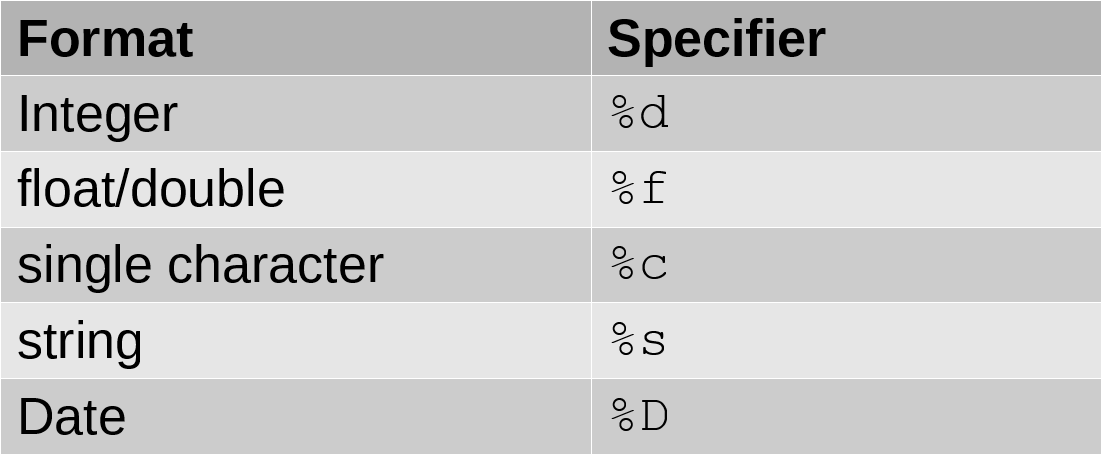

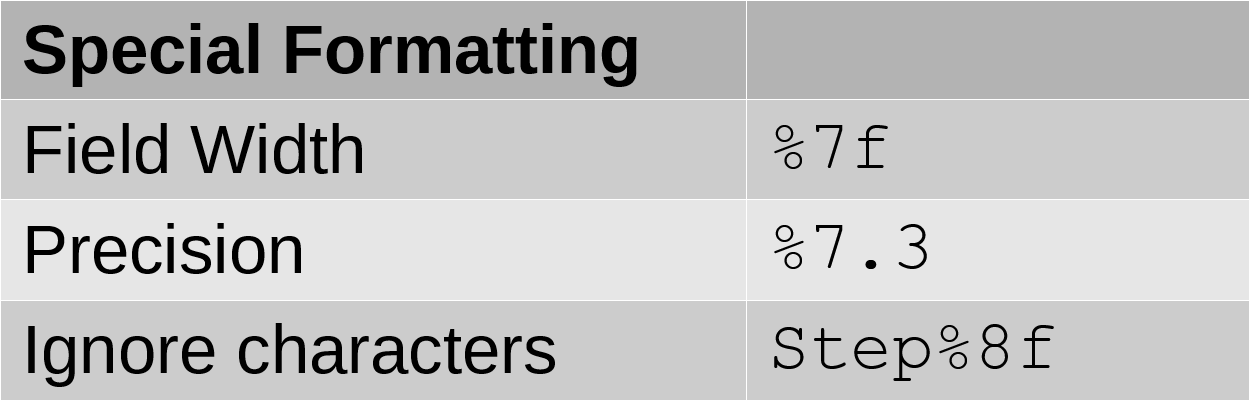

fid = fopen(txtfile)
N = 16*12+2;
Ctxt = textscan(fid,'%s %s %.1f %.1f %.1f %.1f %.1f %.1f %.1f %.1f %.1f %s %.1f %.1f %.1f',N)
fclose(fid);

## Outputting Data

Saving your processed variables is a good idea

Save your workspace (.mat files)

Output the data into a file with commands

- `dlmwrite`

- `csvwrite`

- `xlswrite`

- `writetable`

## `DLMWRITE`

- writes the data array *M* to `<filename> `(any ascii file)

- adds to an existing file with `'-append'`

- specify delimiter or row/column offsets with `Name,Value`pairs or further arguments

## `CSVWRITE`

- writes data array *M *to a *.csv*file

- specify starting row and column of the *.csv*file with <row> and <col>

- *M *must be numeric

- *.csv *file carries only 5 digits of precision   

## `XLSWRITE`

- writes data array *A *to an excel spreadsheet

- *A *can be any type of array

- specify specific sheets and cell ranges to write data to the spreadsheet

## `WRITETABLE`

- writes table *T* to <filename> OR *T.txt*

- each column of each variable in *T *becomes a column in the output file

- variable names of *T* become column headings in the first line of the file